**Evaluación - A01734193**

Dado el sigieunte robot, calcula las velocidades lineales y angulares del siguiente robot:

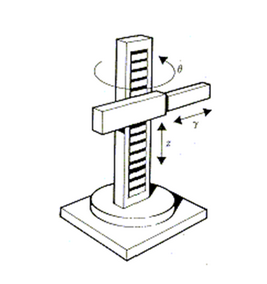

Antes de poder calcular las velocidades correspondiantes, el primer paso que se debe de a hace es analizar el sistema de tal forma que se pueda indentificar el numero de grados de libertad que posee y conocer cuales son las diferentes transformaciones que se deben de aplicar a cada articualcion para que lleguen a la misma referencia que la de la imagen

Como se puede obsevar en la figura ANTERIROR el robot poseé 3 GLD:

- El primero seria la articulacion rotatoria que abarca desde la base hasta el extremo mas alto de la rrore..

- El segundo seria la rotacion prismatica vertical.

- El tercero seria la rotcacion prismatica horizonatal

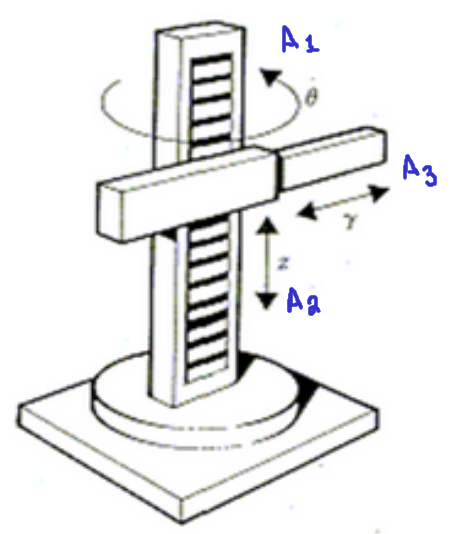

% Etapa 01 --- Declaran de parametros basicos

% Definimos el vector que repsenta el tipo de articulaciones:
% 1 --- Prismaticas
% 0 --- Rotacionales

art_t = [0 1 1];

% A la par se declaran las variables simbolicas que representaran las
% longitudes los rangos de movimeintos que pueden tener estas
% articualciones
syms th1(t) l1 l2 t 

% Posteriroemente se crea el vector de coodernadas articulaes
pos = [th1, l1, l2];

% Calculo de los grados de libertad
GDL = size(art_t, 2);

Una vez encontradas las articualaciones y haber definido su tipo, lo que se debe de hacer es identificar cuales son los ejes de referencia individuales que cada uno de estos tiene.

Para esto primero debemos de considerar que el mundo tiene un eje de refencia inicial basado en el que nos da la regla de la mano dercha y que todas las articulaciones inician alineadas a esa referencia, por lo que es necesario transformar las referencias de cada articualacion para hacer que todas coincidan.

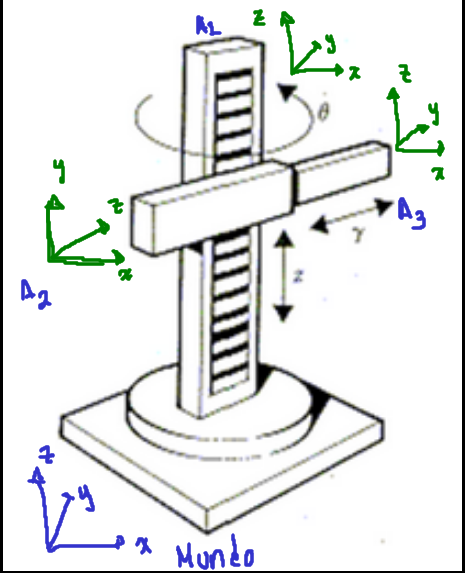

**Articualacion 01 (Rotacional de la base)**

Como esta articualción es de tipo rotacional, el movimeinto que esta puede hacer esta descrito por las funciones trigonometricas seno y coseno por lo que se estable su configuracion de la siguiente manera:

%Posición de la articulación 1 respecto a 0
P(:,:,1) = [cos(th1); sin(th1);  0];

%Matriz de rotación en 'z' de la junta 1
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];

En la segunda linea de codigo de este bloque se establece una rotacion en 'z', pues es la forma en la cual va a girar esta articulación, para poder alinearse respecto al dibujo

**Articualacion 02 (Prismatica vertical)**

Como esta articualción es de tipo prismatica y unicamente tiene movimiento en 'z' y este puede ser de maximo la logitud  de L1, estable su configuración de la siguiente manera:

%Posición de la articulación 1 respecto a 0
P(:,:,2)= [0; 0; l1];

%Matriz de rotación de la junta 1 respecto a -90º
R(:,:,2)= [1 0 0;
           0 0 1;
           0 -1 0];

En este caso la segunda linea del bloque de codigo anterior indica que se debe hacer una rotacion de  -90 grados sobre el eje 'z' para poder alinea los marcos de referencia de la articulacion uno y la dos.

**Articualacion 03 (Prismatica horizontal)**

Como esta articualción es de tipo prismatica y unicamente tiene movimiento en 'y', y este puede ser de maximo la logitud L2, estable su configuración de la siguiente manera:

% --- Articulación 3 (Prismatica Horizonal) --- 

%Posición de la articulación 2 respecto a 1
P(:,:,3)= [0; l2; 0];

%Matriz de rotación de la junta 2 respecto a 1
R(:,:,3)= [1 0 0;
           0 1 0;
           0 0 1];

En este caso la segunda linea contiene la matriz identidad, lo que indica que no habra rotaciones en los tres ejes 'x', 'y', 'z' , pues esta articulacion ya cuenta con el eje de rotacion respecto a la articulacion anterior.

Una vez configuradas cada una de las partes del sistema  se procede a calcular el vector de velocidades generales

% Del mismo modo se crea el vector general de velocidades
vel = diff(pos, t)

$$vel(t) = \left(\begin{array}{ccc} \frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right) & 0 & 0 \end{array}\right)$$

Despues de esto se inicializan las matrices de transformacion, las cuales sirven para describir cual fue el movimiento de todo el sistema:

%Creamos un vector de ceros
Vector_Zeros = zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 

*Nota: El vector de ceros y el '1' Pue se agrega al final de cada matriz, sirven unicamente para cuadrar las matrices (4 x 4)*

*Por lo que para poder crear estas matirices de debe de hacer un ciclo que recorrra cada uno de los grados de libertad del sistema y calcule las matrices  de transformacion correspondientes para cada articulacion.*

for i = 1:GDL

    i_str= num2str(i);

   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i) = simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);

   %pretty (A(:,:,i));

   %Globales

    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);

    catch
       T(:,:,i)= A(:,:,i);

    end

    disp(strcat('Matriz de Transformación global T', i_str));

    T(:,:,i)= simplify(T(:,:,i));

    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);

    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));

end

Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0, cos(th1(t)) \
|                                           |
| sin(th1(t)),  cos(th1(t)), 0, sin(th1(t)) |
|                                           |
|      0,            0,      1,      0      |
|                                           |
\      0,            0,      0,      1      /



Matriz de Transformación global T2


/ cos(th1(t)),  0, -sin(th1(t)), cos(th1(t)) \
|                                            |
| sin(th1(t)),  0,  cos(th1(t)), sin(th1(t)) |
|                                            |
|      0,      -1,       0,           l1     |
|                                            |
\      0,       0,       0,           1      /



Matriz de Transformación global T3


/ cos(th1(t)),  0, -sin(th1(t)), cos(th1(t)) \
|                                            |
| sin(th1(t)),  0,  cos(th1(t)), sin(th1(t)) |
|                                            |
|      0,      -1,       0,        l1 - l2   |
|                                            |
\      0,       0,       0,           1      /



Estas matrices de transformacion resultantes van a indicar cuales son las posiciones y orientaciones finales de cada una de las articualaciones , por lo que se queremos calcular las velocidades resultantes basta con derivar estas funciones (calcular el jacobiano)

% Jacobiano de velocidades lineales y velocidades angulares
Jv_a(:,GDL) = PO(:,:,GDL);
Jw_a(:,GDL) = PO(:,:,GDL);

for k = 1:GDL

    if art_t(k)==0 

       %Para las juntas de revolución
        try

            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);

        catch

            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad

        end

    else

%         %Para las juntas prismáticas

        try

            Jv_a(:,k) = RO(:,3,k-1);

        catch

            Jv_a(:,k) = [0,0,1];

        end

            Jw_a(:,k) = [0,0,0];
            
     end

 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);

En este caso se hizo de manera analica, pues para mi es mucho mas facil ver que es lo que pasa con cada una de las articulaciones ademas de que este metodo funciona para juntas prismaticas y rotacionales.

Finalmente se imprimen los resultados

disp('Velocidad lineal obtenida mediante el Jacobiano analitico');

Velocidad lineal obtenida mediante el Jacobiano analitico


V = simplify (Jv_a * vel');
pretty(V);

/   _________             \
|    d                    |
| - -- th1(t) sin(th1(t)) |
|   dt                    |
|                         |
|  _________              |
|   d                     |
|  -- th1(t) cos(th1(t))  |
|  dt                     |
|                         |
\            0            /



En este caso el valor que esta en 0, hace referencia la aritculacion rotacional pues esta no cuentan con velocidad lineal, lo cual tiene sentido, pues es de tipo rotacional, lo que indicia que el movimiento debe ser angular y no lineal.


disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*vel');
pretty(W);

/     0     \
|           |
|     0     |
|           |
| _________ |
|  d        |
| -- th1(t) |
\ dt        /



En este caso los valores que estan en 0 indican que las articulaciones 3 y 2 respectivamente no cuentan con velocidad angular, lo cual tiene sentido, pues son de tipo prismatica, lo que indicia que el movimiento debe ser lienal no angular.